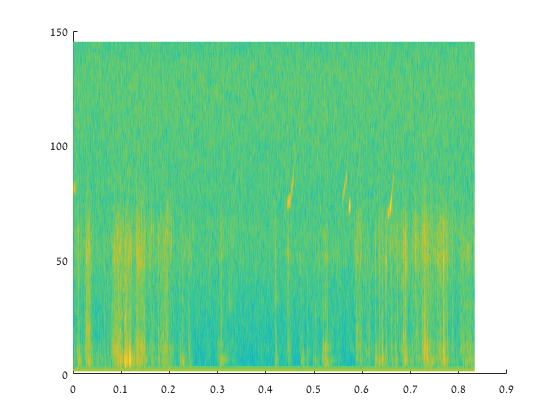

fs = 3e5;
normVec = vec.*max(max(abs(vec))).*10;
[s,f,t,ps] = spectrogram(normVec,hamming(128),64,256,fs,'yaxis');
s = log10(abs(s*2));
[~,ind] = min(abs(f-1000));
Yinds = ind:(ind+124-1);
s = s(Yinds,:);
f = f(Yinds,:)./1000;
figure;
surface(t,f,s,'EdgeColor','none');

new_fs = floor(numel(t)*fs/numel(vec));
[featuresCell]=...
    prepare_file_for_model(s',...
    [],1,0,51,1,fs,new_fs);

features = featuresCell(1:end);
 features_big = {cat(4,features{:,:})};

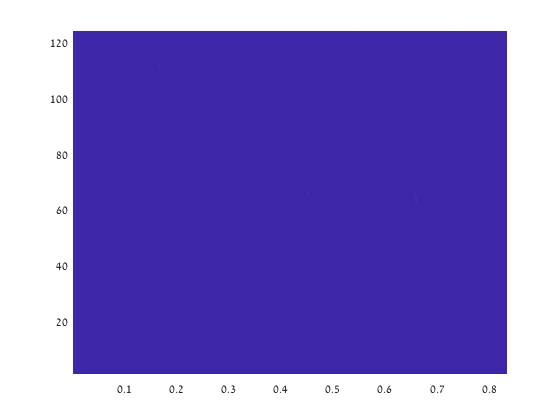

    input_size = size(features,1);
    labels_vector = {cat(2,labels_vector{:,:})};
    file_size = input_size;
    
    
    
    all_features_sample = features_big{:};
    
        act1 = (activations(tested_net,features_big,'addition'));
       
        
    size(act1);
    if iscell(act1)
        I = act1{:,:};
        I_copy = I;
        [numFeatures,numTimes]=size(I_copy);
    else
        [numFeatures,width,numFilters,numTimes]=size(act1);
        mid_section = floor(width/2)+1;
        act1_slice = (act1(:,mid_section,:,:));
        act1_t = permute(act1_slice,[1,2,4,3]);
        act1_t = reshape(act1_t,numFeatures,1,[]);

        I_copy = imtile((act1_t),'GridSize',[numFilters numTimes]);

    end
    
    
   
    
        act1_t_map = I_copy;
        
    %Concatenate the feature map
    map_in_fc = (squeeze(all_features_sample(:,26,:,:)));

 act1_t_map = cat(1,act1_t_map,map_in_fc);
 figure;
    hSurf= surface(I_copy,'EdgeColor','none');
 xTime = (1:numTimes)/new_fs;
    hSurf.XData = (xTime);
    
    axis tight

%     colormap gray

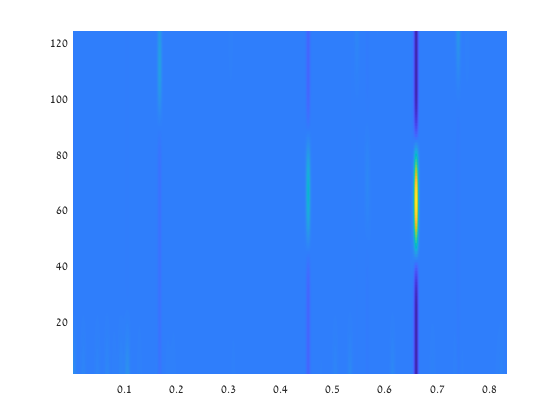

I = I_copy;
YPred_prob = prob;
 I = imgaussfilt(I,[10,10]);
%  I = I.*(YPred_prob>0.01);
 I = softmax(I);
 I = imgaussfilt(I,[10,10]);
%  I(I<0.01) = 0;

 figure;
     hSurf= surface(I,'EdgeColor','none');
 xTime = (1:numTimes)/new_fs;
    hSurf.XData = (xTime);
         
    axis tight